The purpose of this live script is to explain sacttering and perform some computations with it involving larger quantities of atoms to see what happends for multiple scattering. The first thing we will do is study how the visual wavelength change as a function of angle. I.e what will be the resulting wavelength of light at what angle. In this case, we will have the light incident on the horizontal right being positive, and theta will represent the upwards(+) scattering angle. 

%starting with a simple example
lambda = 520*10.^-9; %meters
theta = 23; %degrees
lambda_prime=compton_scatter(lambda,theta)

lambda_prime = 5.2000e-07

So what do we notice here? absolutely no change in the wavelength of light. This is due to the fact that Compton Scattering is for wavelengths of light which are much shorter than the visual band. So, let's plot a series of wavelengths and find out when Compton Scattering become relevant.

%work out when Compton becomes relevant
clear all
theta = 35;
n=1;
for i=1:18
    lambda_prime(n)=compton_scatter(10.^-i,theta);
    lambda(n)=10.^-i;
    n=n+1;
end
disp(lambda_prime-lambda)

   1.0e-12 *

    0.4395    0.4395    0.4395    0.4395    0.4395    0.4395    0.4395    0.4395    0.4395    0.4395    0.4395    0.4395    0.4395    0.4395    0.4395    0.4395    0.4395    0.4395



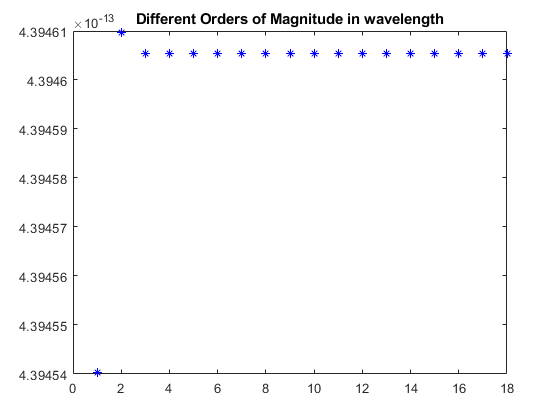

%plot this vector
plot(lambda_prime-lambda,'b*')
title('Different Orders of Magnitude in wavelength')

So it looks like the effect is smaller at the high wavelengths, than jumps and stabilises. This is not a very interesting graph, and upon inspection of the formula, we can see that Compton scaterring with have the largest effect around 10.^-12. So let's look at this range.

% Closer to the range of interest
clear all
theta = 180;
exp=12;
n=1;
for i=1:1:10
    lambda_prime(n)=compton_scatter(i*10.^-exp,theta);
    lambda(n)=i*10.^-exp;
    n=n+1;
end
disp(lambda_prime-lambda)

   1.0e-11 *

    0.4860    0.4860    0.4860    0.4860    0.4860    0.4860    0.4860    0.4860    0.4860    0.4860



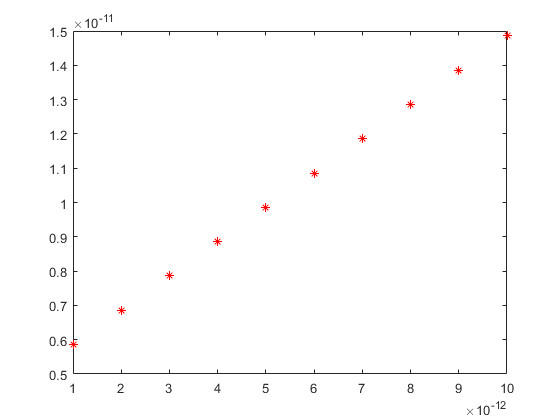

%plot this vector
plot(lambda,lambda_prime,'r*')

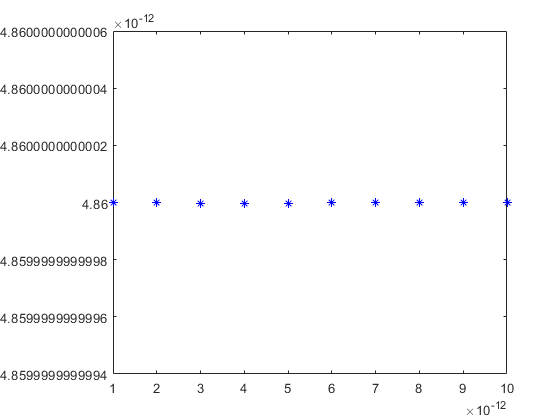

plot(lambda,lambda_prime-lambda,'b*')

This again is just a linear graph and not particularily nice to look at. It illustrates the linear relationship that we're expecting by changing the input wavelength. Now, let's see what happends as we change the angle for a given wavelength.

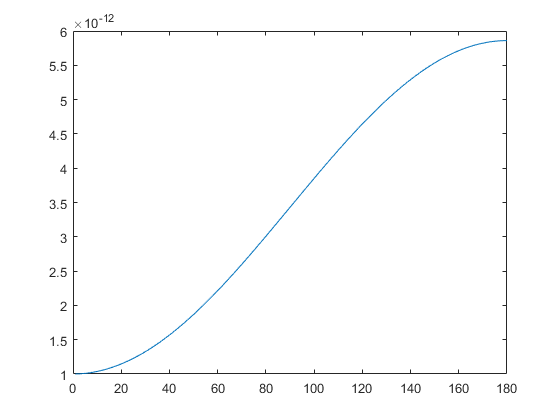

% Closer to the range of interest
clear all

n=1;
for i=1:1:180
    lambda_prime(n)=compton_scatter(10.^-12,i);
    theta(n)=i;
    n=n+1;
end
plot(theta,lambda_prime)

I purposefully chose this range to make a solid point. We are simply adding the Compton wavelength to the initial wavelength. Since the Compton  wavelength is at this magnitude the most visual effect possible will be present. Overall we can see that compton scattering is taking the imput wavelength and subtracting the momentum that is deposited upon the particle it's colliding with. An excellent entry level scattering problem to study how light interacts with particles, we now want to move on to a more elaborate scattering problem. 